# Tutorial 5.1

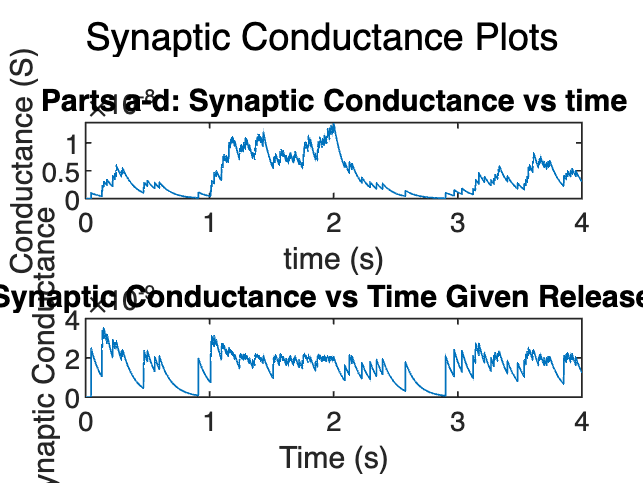

clear
% time vector (Part: a) Eric
dt = 0.1*10^-3; % 0.1ms
tvec = 0:dt:4; % 0 to 4 sec


% firing vector (Part: b) Eric
fvec = zeros(size(tvec));
for i = 1: 10000 
    fvec(i) = 20; % 20hz 1st sec
end
for i = 10001:20000
    fvec(i) = 100; % 100hz 2nd sec
end
for i = 20001:30000
    fvec(i) = 10; % 10hz 3rd sec
end
for i = 30001:40000
    fvec(i) = 50; %50hz 4th sec
end


%Spike train (Part: c) Eric
spikes = rand(size(tvec)) < dt * fvec; %randomize spike trains


%Synaptic Conductance Vector (Part: d) Eric
%define parameters
dG = 1*10^-9; %1nS increments
tau = 100*10^-3;% 100ms
%define vectors
Gsyn = zeros(size(tvec));
Gsyn(1) = 0; % no conductance
%Euler's method
for i = 2:length(tvec)
dGsyn_over_dt = -1*Gsyn(i-1)/tau;
Gsyn(i) = Gsyn(i-1) + dGsyn_over_dt * dt;
    if spikes(i) == 1
    Gsyn(i) = Gsyn(i) + dG;
    end
end

% Part a-d plot
figure();
subplot(2,1,1);
plot(tvec, Gsyn)
title('Parts a-d: Synaptic Conductance vs time')
xlabel('time (s)')
ylabel('Conductance (S)')


%Release Probabilty (Part: e) Anthony
p0 = 0.5; %release probability
Dvec = zeros(size(tvec));
Dvec(1) = 1;
tau_D = 0.25; %seconds

for i = 2:length(tvec)
    dD_over_dt = (1-Dvec(i-1))/tau_D;
    Dvec(i) = Dvec(i-1) + dD_over_dt*dt;
    if spikes(i) == 1
        Dvec(i) = Dvec(i) - p0*Dvec(i);
    end
end


% Second Synaptic Conductance Vector (Part: f) Anthony
% Define parameters
dG_max = 5e-9; % 5nS
tau = 100 * 10^-3; % 100ms

% Define vectors
Gsyn2 = zeros(size(tvec));
Gsyn2(1) = 0; % No conductance

% Euler's method
for i = 2:length(tvec)
    dG = dG_max * p0 * Dvec(i-1); % 1nS increments
    dGsyn2_over_dt = -1 * Gsyn2(i-1) / tau;
    Gsyn2(i) = Gsyn2(i-1) + dGsyn2_over_dt * dt;
    if spikes(i) == 1
        Gsyn2(i) = Gsyn2(i) + dG;
    end
end

% Part e-f plot
subplot(2,1,2);
plot(tvec, Gsyn2);
title('Parts e-f: Synaptic Conductance vs Time Given Release Probability')
xlabel('Time (s)')
ylabel('Synaptic Conductance')
sgtitle('Synaptic Conductance Plots')

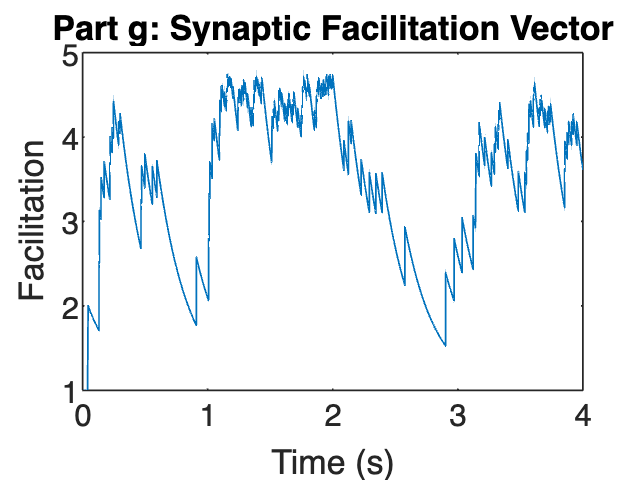



% Synaptic Facilitation Vector (Part: g) Anthony
% Define parameters
p0F = 0.2;
Ffac = 0.25;
F_max = 1 / p0F; % 5nS
tau_F = 0.25; % seconds

% Define vectors
Fvec = zeros(size(tvec));
Fvec(1) = 1; % Initial value as 1
for i = 2:length(tvec)
    dF_over_dt = (1 - Fvec(i-1)) / tau_F;
    Fvec(i) = Fvec(i-1) + dF_over_dt * dt;
    if spikes(i) == 1
        Fvec(i) = Fvec(i) + Ffac * (F_max - Fvec(i-1));
    end
end

% Part g plot
figure;
plot(tvec, Fvec);
title('Part g: Synaptic Facilitation Vector');
xlabel('Time (s)');
ylabel('Facilitation');

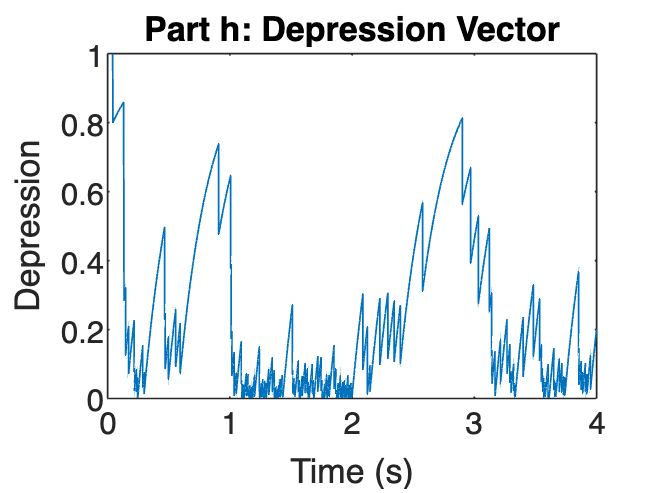



% Synaptic Depression Vector (Part: h) Mauricio
% Define parameters
p0D = 0.2; % Release Probability
D_max = 1 / p0D;
tau_D = 0.25;

% Define vectors
Dvec = zeros(size(tvec)); % Depression Vector
Dvec(1) = 1;
for i = 2:length(tvec)
    dD_over_dt = (1 - Dvec(i-1)) / tau_D;
    Dvec(i) = Dvec(i-1) + dD_over_dt * dt;
    if spikes(i) == 1
        Dvec(i) = Dvec(i) - (p0D * Fvec(i - 1) * Dvec(i - 1));
    end
end

% Part h plot
figure;
plot(tvec, Dvec);
title('Part h: Depression Vector');
xlabel('Time (s)');
ylabel('Depression');

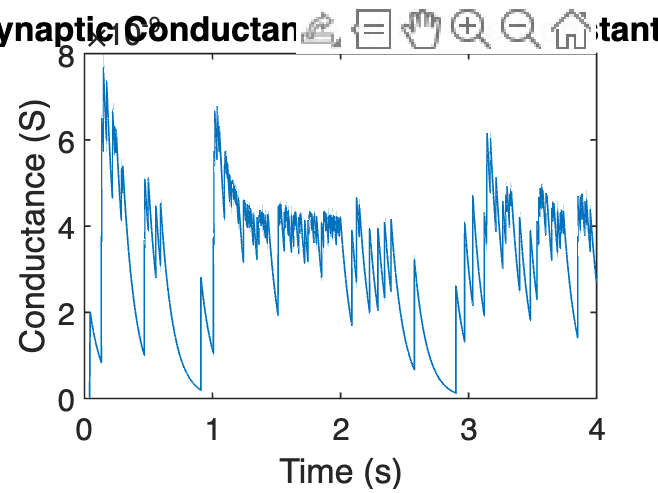



% Third Synaptic Confuctance Vector (Part: i) Mauricio
% Define parameters
dG3_max = 4e-9; % 5nS
tau_i = 100 * 10^-3; % 100ms

% Define vectors
Gsyn3 = zeros(size(tvec));
Gsyn3(1) = 0; % No conductance

% Euler's method
for i = 2:length(tvec)
    dG = dG3_max * p0 * Fvec(i-1) * Dvec(i-1); % 1nS increments
    dGsyn3_over_dt = -1 * Gsyn3(i-1) / tau_i;
    Gsyn3(i) = Gsyn3(i-1) + dGsyn3_over_dt * dt;
    if spikes(i) == 1
        Gsyn3(i) = Gsyn3(i) + dG;
    end
end

% Part i Plot
figure;
plot(tvec, Gsyn3);
title('Part i: Synaptic Conductance with Time Constant = 100 ms');
xlabel('Time (s)');
ylabel('Conductance (S)');